%loading the 4 images of different intensity functions
I1 = rgb2gray(imread('picture1.jpeg'));
I2 = rgb2gray(imread('picture2.jpeg'));
I3 = rgb2gray(imread('picture3.jpeg'));
I4 = rgb2gray(imread('picture4.jpeg'));
%figure(1);
%subplot(2,2,1); imshow(I1); title('I1, \theta = 0');
%subplot(2,2,2); imshow(I2); title('I2, \theta = \pi/2');
%subplot(2,2,3); imshow(I3); title('I3, \theta = \pi');
%subplot(2,2,4); imshow(I4); title('I4, \theta = 3\pi/2');

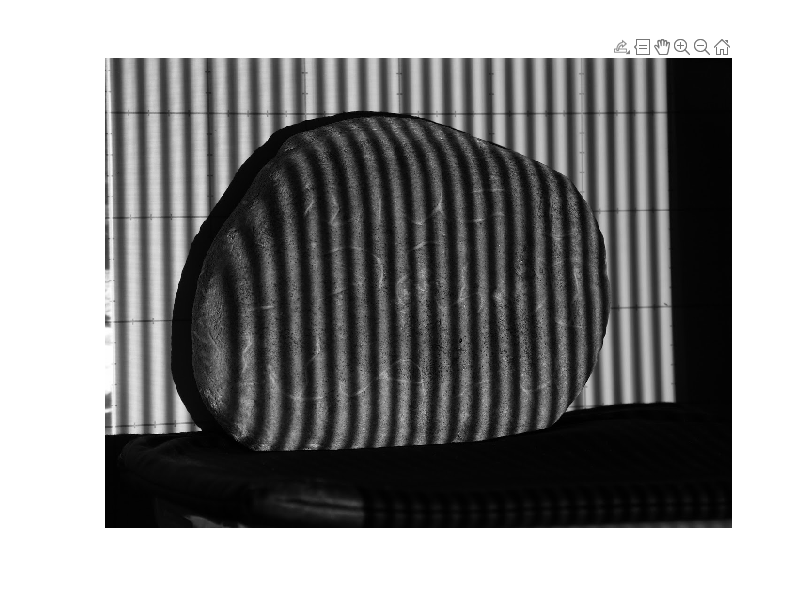

%crop region of interest
[J1, RECT] = imcrop(I1);

J2 = imcrop(I2, RECT);
J3 = imcrop(I3, RECT);
J4 = imcrop(I4, RECT);
%figure(2);
%subplot(2,2,1); imshow(J1); title('ROI \theta = 0');
%subplot(2,2,2); imshow(J2); title('ROI \theta = \pi/2');
%subplot(2,2,3); imshow(J3); title('ROI \theta = \pi');
%subplot(2,2,4); imshow(J4); title('ROI \theta = 3\pi/2');

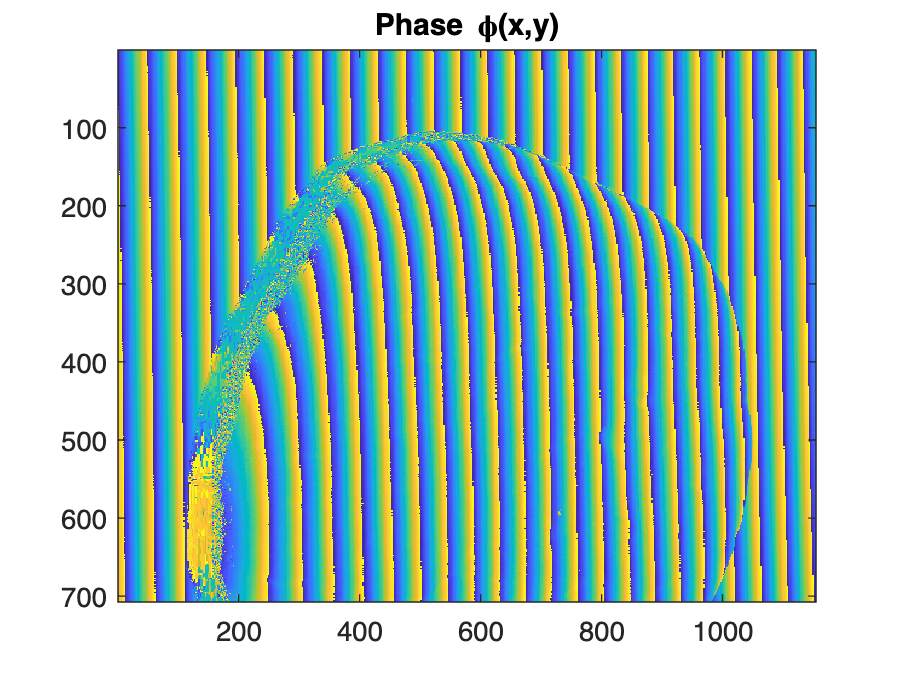

%calculating the phase
Num = double(J4) - double(J2);
Den = double(J1) - double(J3);
PHI = atan2(Num, Den);
figure(3); imagesc(PHI); title('Phase \phi(x,y)');

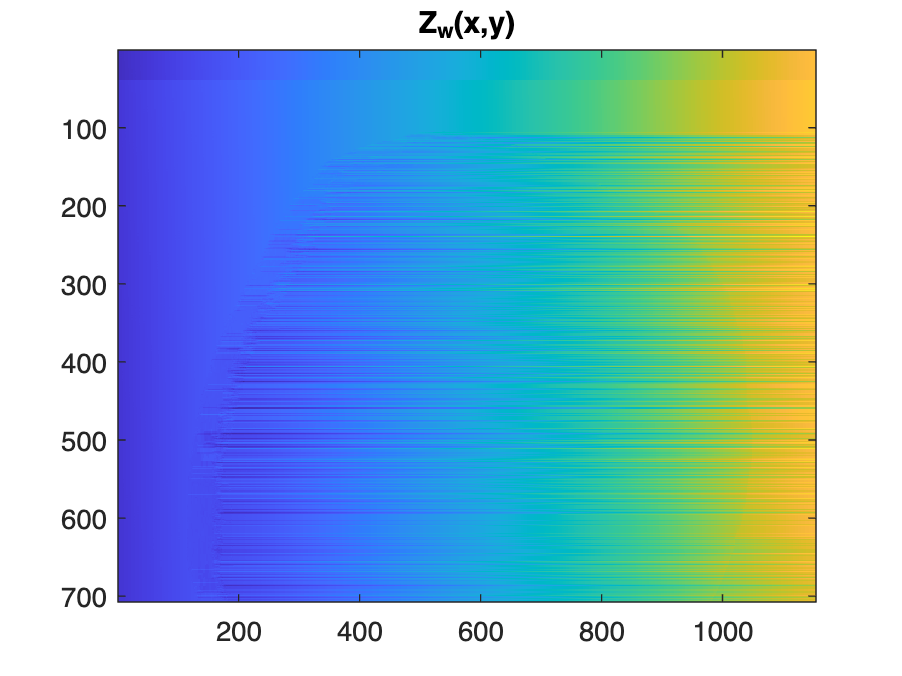

%unwrapping the phase
Z_w = unwrap(PHI,[],2);
figure(4); imagesc(Z_w); title('Z_{w}(x,y)');

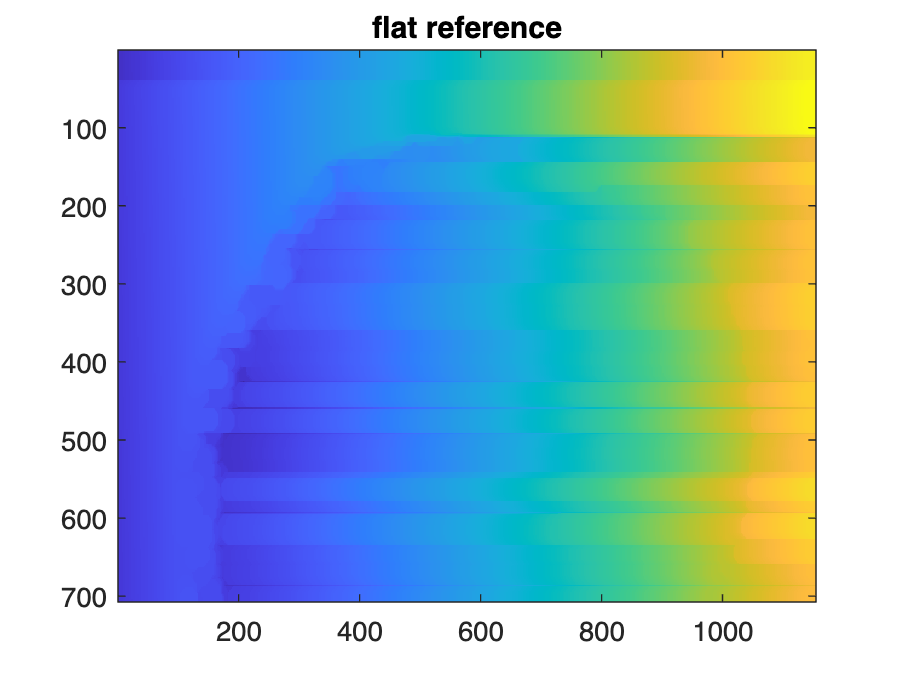

%estimating the reference
se = strel('disk',15);
background = imopen(Z_w,se);
figure(5); imagesc(background); title('flat reference');

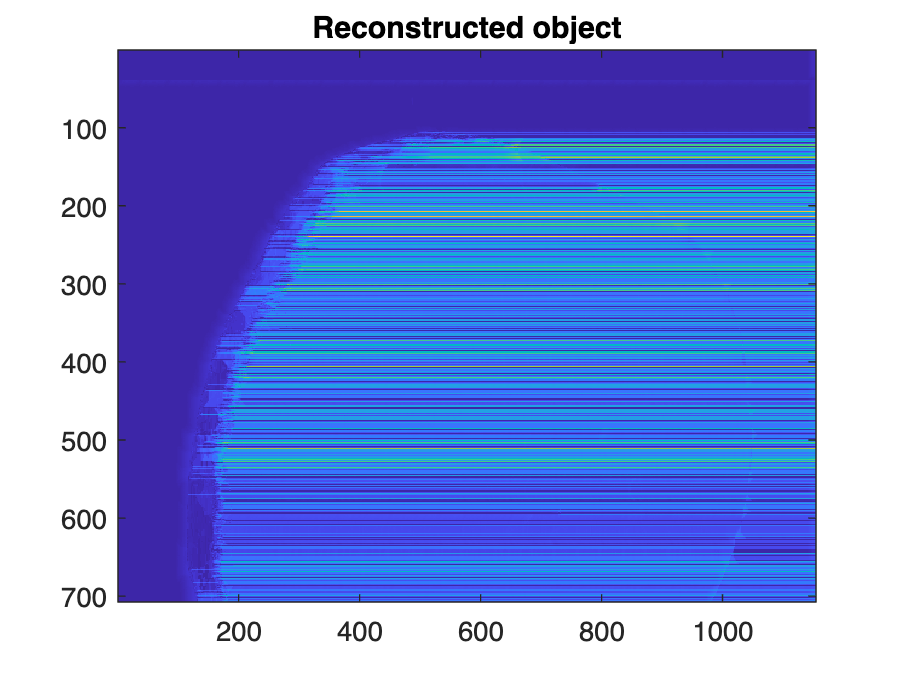

%getting phase difference
Obj = Z_w-background;
figure(6); imagesc(Obj); title('Reconstructed object');

figure(7); 
s = surf(Obj);
s.EdgeColor = 'none';

%horizontal filter
%applying FFT to improve reconstructed image
Obj_fft = fftshift(fft2(Obj(:,1:115)));
size_fft = size(Obj_fft);
C=ones(size_fft);
for (y=round(size_fft(:,2)/2)+10 : size_fft(:,2)) %right mask
    for (x= round(size_fft(:,1)/2)-2: round(size_fft(:,1)/2)+2)
        C(x,y)=0;
    end
end
for (y= 1:round(size_fft(:,2)/2)-10) %left mask
    for (x= round(size_fft(:,1)/2)-2: round(size_fft(:,1)/2)+2)
        C(x,y)=0;
    end
end
Obj_fft_filtered = Obj_fft.*C;

%vertical filter
%applying FFT to improve reconstructed image
Obj_fft = fftshift(fft2(Obj(:,1:140)));
size_fft = size(Obj_fft);
C=ones(size_fft);
for (y=round(size_fft(:,2)/2)-5 : round(size_fft(:,2)/2)+5) %right mask
    for (x= 1: round(size_fft(:,1)/2)-5)
        C(x,y)=0;
    end
end
for (y=round(size_fft(:,2)/2)-5 : round(size_fft(:,2)/2)+5) %left mask
    for (x= round(size_fft(:,1)/2)+5: round(size_fft(:,1)))
        C(x,y)=0;
    end
end
Obj_fft_filtered = Obj_fft.*C;

%vertical filter
%applying FFT to improve reconstructed image
Obj_fft = fftshift(fft2(Obj(:,1:115)));
size_fft = size(Obj_fft);
C=ones(size_fft);
for (y=round(size_fft(:,2)/2) : round(size_fft(:,2)/2)) 
    for (x= 1: round(size_fft(:,1)/2)-100)
        C(x,y)=0;
    end
end
for (y=round(size_fft(:,2)/2) : round(size_fft(:,2)/2)) 
    for (x= round(size_fft(:,1)/2)+100: round(size_fft(:,1)))
        C(x,y)=0;
    end
end
%horizontal
for (y=round(size_fft(:,2)/2)+20 : size_fft(:,2)) %right mask
    for (x= round(size_fft(:,1)/2)-2: round(size_fft(:,1)/2)+2)
        C(x,y)=0;
    end
end
for (y= 1:round(size_fft(:,2)/2)-20) %left mask
    for (x= round(size_fft(:,1)/2)-2: round(size_fft(:,1)/2)+2)
        C(x,y)=0;
    end
end
Obj_fft_filtered = Obj_fft.*C;

figure(8);
imagesc(log(abs(Obj_fft))); colormap(gray); title('FFT of Object'); 
figure(9);
cleimagesc(log(abs(Obj_fft_filtered))); colormap(gray);  title('Filtered FFT'); 

Obj_fft_filtered_inverse = ifft2(ifftshift(Obj_fft_filtered));
figure(10); 
imagesc(double(abs(Obj_fft_filtered_inverse))); 
title('Reconstructed Object with FFT');

%getting phase difference
figure(11); 
Obj_filtered = double(abs(Obj_fft_filtered_inverse));
s = surf(Obj_filtered);
s.EdgeColor = 'none';